# Autonomous Ground Vehicle Use Case Evaluation

The overarching goal of the model is to enable the economic feasibility of a wide variety of autonomous ground vehicle projects to be objectively evaluated.

To achieve this goal, the model aims to answer the following questions:

- What is the net present value of an investment in an automated ground vehicle for a specific application use case compared to the business as usual case?

- What is the sensitivity of the amortization period to the input assumptions? In other words, which input assumptions have the greatest effect on the amortization period for the project?

- Which implications do the deployment of automated ground robots have on manpower needs? In other words, where can human resources be more effectively allocated?

Assumptions

clear

% Financial
discountRate = 0.05;  % Five percent per annum
% Energy
electricityPrice = 0.23; % EUR/kWh
dieselPrice = 1.79; %EUR/L
dieselEnergy = 9.6; % kWh/L
% Data
dataCarriage = 0.7; %EUR/MB
% Lifecycle
YearsOfOperation=7.0; %Years that the robotic system is in operation
% Technology Readiness
TechnologyReadiness = 5.0; %Technology validated in relevant environment (industrially relevant environment in the case of key enabling technologies)
% Company Acceptance
CompanyAcceptance = 0.7; %represents a 'good' level of AGV acceptance within a company
% Mission Similarity
MissionSimilarity = 0.8; %represents an 'excellent' level of mission similarity
% Mission Determinism
MissionDeterminism = 0.6; %represents a 'sufficient' level of mission determinism

Assumptions=struct;
Assumptions.discountRate=discountRate;
Assumptions.electricityPrice=electricityPrice;
Assumptions.dieselPrice=dieselPrice;
Assumptions.dieselEnergy=dieselEnergy;
Assumptions.dataCarriage=dataCarriage;
Assumptions.YearsOfOperation=YearsOfOperation;
Assumptions.TechnologyReadiness=TechnologyReadiness;
Assumptions.CompanyAcceptance=CompanyAcceptance;
Assumptions.MissionSimilarity=MissionSimilarity;
Assumptions.MissionDeterminism=MissionDeterminism;

Assumptions_py = py.dict(Assumptions);

For the baseline case, we reach assumptions resulting in an almost-zero Net Present Value for a project replacing a human-driven vehicle with an autonomous version.

%  CURRENT Mission Inputs
MissionLength=2; %km driven per misson round moving material
MaterialToMove=200; %amount of material (kg, m^3 etc) required to be moved from A to B for the mission
YearlyOperationDays = 212; %operating days per year. Note: differentiate availability for AGV vs human using max shift length

%  CURRENT Operator driven vehicle use inputs

VehicleCost=74000; %EUR
VehicleEnergyConsumption = 6.5; %L/100km
OperatorHourlyWage = 51; %EUR/hr
VehicleMaintenance = 120; %EUR/month
VehicleEOLCost = 1800; %EUR for end of life disposal
VehicleAverageSpeed=12; %km/hr
VehicleMaterialCapacity = 40; %amount of material (kg, m^3 etc) which can be moved from A to B for the mission
VehicleMaxShiftLength = 8; %hrs max which the vehicle can operate

%  CURRENT AGV use inputs
AGVCost = 115000; %EUR/vehicle  Note - set to zero if Leasing cost is set (Default 115000)
AGVLeasing = 0; %EUR/vehicle/year  Note - set to zero if AGV cost is set (Default 7000)
AGVMaintenance = 200; %EUR/month
AGVEOLCost = 4000; %EUR for end of life disposal
AGVAverageSpeed= 3; %km/hr (including all stop and blocked time caused by obstacles)
AGVChargeRate= 3; %kW
AGVDisengagementPerKm = 0.01; %disengagements per driven km
AGVDisengagementTime = 5; %minutes per disengagement
AGVMaterialCapacity = 20; %amount of material (kg, m^3 etc) which can be moved from A to B for the mission
AGVEnergyConsumption = 0.14; %kWh/km
AGVMaxShiftLength = 24; %if the AGV is unable to operate 24/7, an additional penalty can be added here
AGVDataUse = 4; %MB/day

Construct input and create Python Dictionary.

Inputs = struct;
Inputs.MissionLength=MissionLength;
Inputs.MaterialToMove=MaterialToMove;
Inputs.YearlyOperationDays=YearlyOperationDays;

Vehicle=struct;
Vehicle.VehicleAverageSpeed=VehicleAverageSpeed;
Vehicle.VehicleMaterialCapacity=VehicleMaterialCapacity;
Vehicle.VehicleMaxShiftLength=VehicleMaxShiftLength;
Vehicle.VehicleCost=VehicleCost;
Vehicle.VehicleEnergyConsumption=VehicleEnergyConsumption;
Vehicle.OperatorHourlyWage=OperatorHourlyWage;
Vehicle.VehicleMaintenance=VehicleMaintenance;
Vehicle.VehicleEOLCost=VehicleEOLCost;
Inputs.Vehicle=Vehicle;

AGV=struct;
AGV.AGVCost=AGVCost;
AGV.AGVLeasing=AGVLeasing;
AGV.AGVMaintenance=AGVMaintenance;
AGV.AGVEOLCost=AGVEOLCost;
AGV.AGVAverageSpeed=AGVAverageSpeed;
AGV.AGVChargeRate=AGVChargeRate;
AGV.AGVDisengagementPerKm=AGVDisengagementPerKm;
AGV.AGVDisengagementTime=AGVDisengagementTime;
AGV.AGVMaterialCapacity=AGVMaterialCapacity;
AGV.AGVEnergyConsumption=AGVEnergyConsumption;
AGV.AGVMaxShiftLength=AGVMaxShiftLength;
AGV.AGVDataUse=AGVDataUse;
Inputs.AGV=AGV;

Inputs_py = py.dict(Inputs);

Run computations

outputs = py.AGVUseCaseFunctions.ModelAGVUseCase(Assumptions_py,Inputs_py);
outputs = struct(outputs);

Plot Case Results

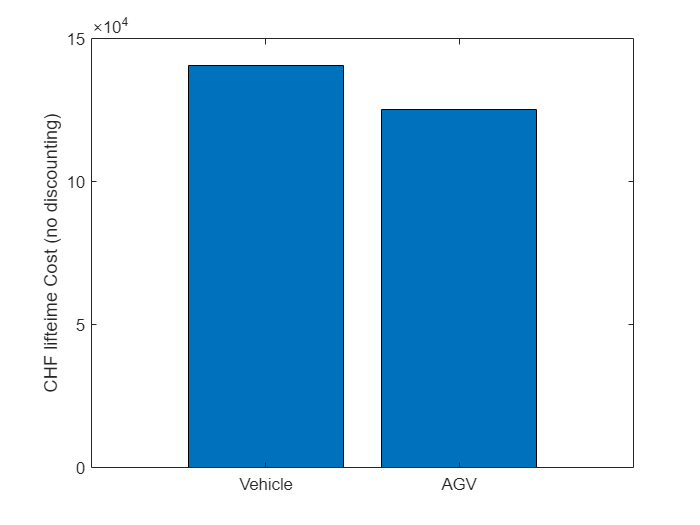

usecase = "Baseline";

vehicleTotalCost = VehicleCost + outputs.CumulativeVehicleAnnualCost + VehicleEOLCost;
AGVTotalCost = AGVCost + outputs.CumulativeAGVAnnualCost+ AGVEOLCost;
bar(["Vehicle", "AGV"],[vehicleTotalCost, AGVTotalCost])
ylabel("CHF lifteime Cost (no discounting)")
ytickformat("%.0f")

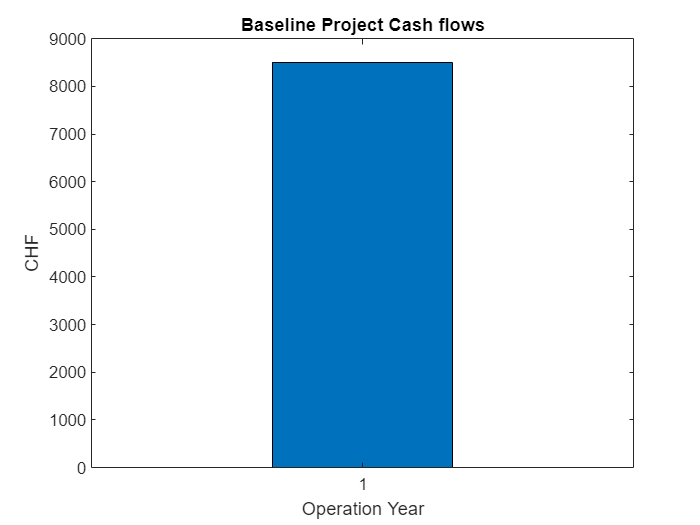

cashFlows = double(outputs.cashFlows);
bar(cashFlows)
title(usecase+" Project Cash flows")
xlabel("Operation Year")
ylabel("CHF")

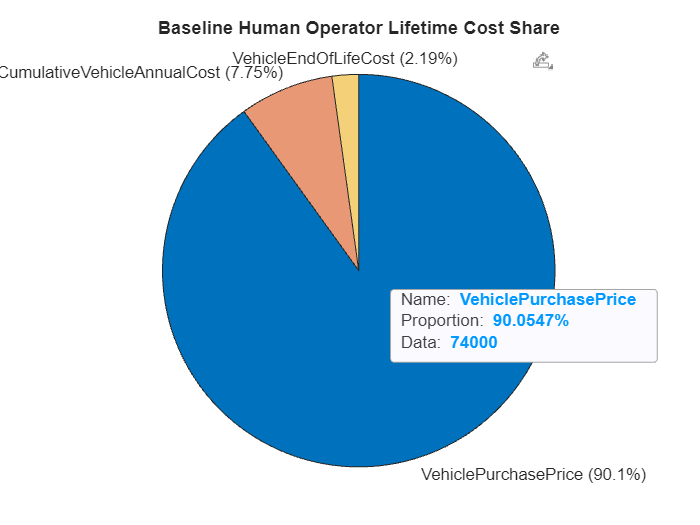

costsBaseline = [VehicleCost, outputs.CumulativeAGVAnnualCost, VehicleEOLCost];
costsAGV = [AGVCost, outputs.CumulativeAGVAnnualCost, AGVEOLCost];

labels = ["VehiclePurchasePrice", "CumulativeVehicleAnnualCost", "VehicleEndOfLifeCost"];
piechart(costsBaseline, labels);
title(usecase+" Human Operator Lifetime Cost Share")

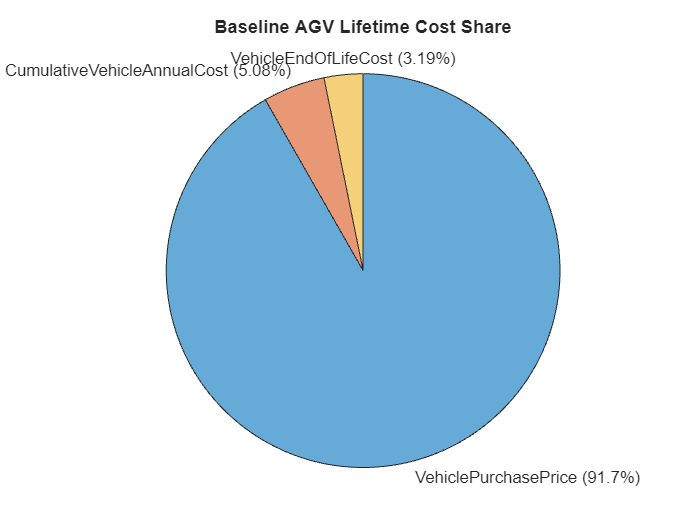

piechart(costsAGV,labels)
title(usecase+" AGV Lifetime Cost Share")

Sensitivity Analysis

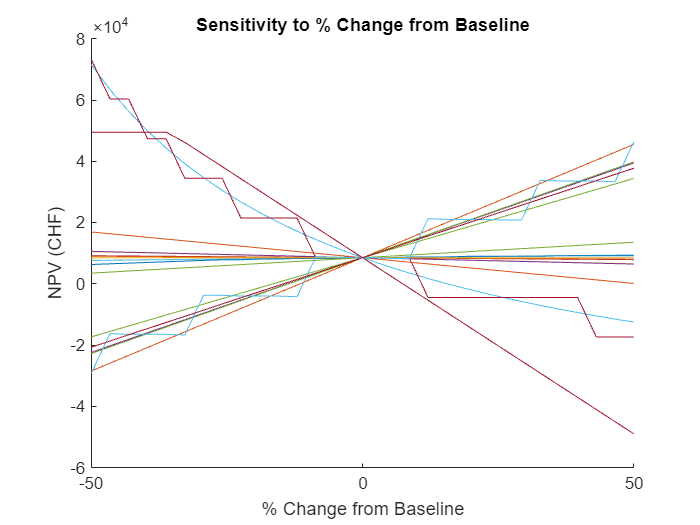

minMaxPercent = 50; % the maximum and minimum percentage to consider
numLevels = 30; % the number of levels of discretization to consider

keys = [fieldnames(Assumptions); fieldnames(Inputs.Vehicle); fieldnames(Inputs.AGV); {'MissionLength'}; {'MaterialToMove'}; {'YearlyOperationDays'}];
keys(ismember(keys,'dieselEnergy')) = [];
keys(ismember(keys,'TechnologyReadiness')) = [];
keys(ismember(keys,'CompanyAcceptance')) = [];
keys(ismember(keys,'MissionSimilarity')) = [];
keys(ismember(keys,'MissionDeterminism')) = [];

minMaxVectors = [];
minMaxValues = [];
npvVectors = [];
slope = [];
for ii=1:numel(keys)
    sensitivityResults = py.AGVUseCaseFunctions.SenstivityAnalysis(py.str(keys{ii}), py.int(minMaxPercent), py.int(numLevels), Assumptions, Inputs);
    sensitivityResults = cell(sensitivityResults);

    minMaxVectors(ii,:) = double(sensitivityResults{1});
    minMaxValues(ii,:) = double(sensitivityResults{2});
    npvVectors(ii,:) = double(sensitivityResults{3});    
    slope(ii,:) = (npvVectors(ii,end)-npvVectors(ii,1))/2*minMaxPercent;
end


figure;
hold on
for ii=1:numel(keys)
    h = plot(minMaxVectors(ii,:)*100, npvVectors(ii,:));
    h.DataTipTemplate.DataTipRows(end+1) = dataTipTextRow("Parameter", repmat(keys(ii), size(h.XData)));
    h.DataTipTemplate.DataTipRows(end+1) = dataTipTextRow("Range", repmat("From "+minMaxValues(ii,1)+" to "+minMaxValues(ii,2), size(h.XData)));   
end
hold off
title("Sensitivity to % Change from Baseline")
xlabel("% Change from Baseline")
ylabel("NPV (CHF)")